# Starter Code for IEEE Signal Processing Cup 2026 on AV Zoom (Task 1 and 2)

[IEEE Signal Processing Cup](https://signalprocessingsociety.org/community-involvement/signal-processing-cup) (SP Cup) aims to inspire young minds to tackle practical technical problems. The problem for the 2026 IEEE SP Cup is "[AV Zoom: Real-Time Audio-Visual Zooming on Smartphones](https://signalprocessingsociety.org/sites/default/files/2025-10/2026_SP_Cup_Competition_Official_Document_FINAL_23Oct2025.pdf)".

This script demonstrates how to construct a simulation to test the performance of your algorithms for Task 1 and Task 2 (2026 SP Cup Official Document), including:

- Simulation scenario setup and synthesis of received signals from a microphone array [1-4] for anechoic chamber (Task 1) and reverberant room  (Task 2) simulations.

- Basic processing with some relevant techniques in MATLAB, such as beamforming [1-2], direction of arrival estimation [5], and speaker separation [6-7].

- Calculation of the required metrics [9] and generation of submission files.

Hope this livescript helps you get started more quickly with SP Cup 2026! More advanced solutions await your exploration and implementation.

clc; clear; close all;

## Simulation Setup

### Parameters Setup

Set simulation scenario parameters such as sampling rate, sound speed and etc.

fs = 16e3;                                 % sampling rate = 16 kHz
c = 340;                                   % speed of sound in air, approximately 340 m/s at 20 °C

desired_sir = 0;                           % desired Signal-to-Interference Ratio (SIR)
desired_snr = 5;                           % desired Signal-to-Noise Ratio (SNR)

num_sources = 2;                           % number of sources 
target_id = 1;                             % id of target source
interf_id = 2;                             % id of interference source

Set other parameters.

t_length_play = 10;                        % time duration for playing an audio
t_play = 1/fs:1/fs:t_length_play;          % time sequence in the duration
num_play_samples = t_length_play*fs;       % number of samples in the duration

### **Room Setup**

Define an shoebox room with the dimensions (width, length and height, respectively) in meters. 

room_dim = [4.9 4.9 4.9];                  % the room's width, length and height in meters
room_surf_num = 6;                         % the shoebox room has 6 surfaces (floor, front, back, left, right, and ceiling)

### **Microphone Array Setup**

Define a 2-microphone Uniform Linear Array [1]. 

mic_positions = [2.41 2.45 1.5; ...
                 2.49 2.45 1.5];
num_mics = size(mic_positions,1);
mic_center = mean(mic_positions,1);
mic_distance = norm(mic_positions(1,:) - mic_positions(2,:));   % distance between the microphones: 8cm

microphone = ...
    phased.OmnidirectionalMicrophoneElement('FrequencyRange',[20 8000]);

phased.OmnidirectionalMicrophoneElement requires Phased Array System Toolbox.

micULA = phased.ULA(num_mics,mic_distance,'Element',microphone);

 Define a wideband collector converts incident wideband wave fields arriving from specified directions into signals to be further processed [1].

% collector = phased.WidebandCollector('Sensor',micULA,'PropagationSpeed',c, ...
%     'SampleRate',fs,'ModulatedInput',false);

### **Audio Sources Setup**

**Target Source: Source 1 (Target Speaker – Male Speech)**

- Azimuth: 90° (directly in front of array)

- Height: 1.5 m

- Position: (2.45, 3.45, 1.5) m

- Dataset: Male speech from MUSAN Corpus ([OpenSLR 17](https://www.openslr.org/17))

target_file = [pwd '\musan\speech\librivox\speech-librivox-0000.wav'];  % a male speech in MUSAN

target_signal = audioread(target_file);
target_signal = target_signal./max(abs(target_signal));

target_positions = [2.45 3.45 1.5];
target_angles = [90 0];                     % azimuth = 90 degree, elevation = 0 degree
% soundsc(target_signal(1:num_play_samples),fs)

Verify the azimuth and elevation angels of the target source.

v = target_positions - mic_center; 
[az_rad, el_rad, ~] = cart2sph(v(:,1), v(:,2), v(:,3));
target_azimuth = rad2deg(az_rad)
target_elevation = rad2deg(el_rad)

**Interference Source: Source 2 (Interference)**

- Azimuth: 40° (to the right-front)

- Height: 1.5 m

- Position: (3.22, 3.06, 1.5) m

- Dataset: Female speech, Babble, traffic/car, café, office fan from MUSAN Corpus (OpenSLR 17)

interf_file = [pwd '\musan\speech\librivox\speech-librivox-0100.wav'];   % a female speech in MUSAN

interf_signal = audioread(interf_file);
interf_signal = interf_signal./max(abs(interf_signal));

interf_positions = [3.22 3.06 1.5];
interf_angles = [40 0];                     % azimuth = 40 degree, elevation = 0 degree
% soundsc(interf_signal(1:num_play_samples),fs)

Verify the azimuth and elevation angels of the interference source.

v = interf_positions - mic_center; 
[az_rad, el_rad, ~] = cart2sph(v(:,1), v(:,2), v(:,3));
interf_azimuth = rad2deg(az_rad)
interf_elevation = rad2deg(el_rad)

**Align Signal Lengths**

Align the target and interference signal lengths using one of two methods: 

- Method 0: Pad the shorter signal with zeros to match the length of the longer signal. 

- Method 1: Truncate the longer signal to match the length of the shorter signal.

method = 1;                                 
if method == 0
    signal_length = max(numel(target_signal),numel(interf_signal));
    target_signal = [target_signal; zeros(signal_length-numel(target_signal),1)];
    interf_signal = [interf_signal; zeros(signal_length-numel(interf_signal),1)];
else
    signal_length = min(numel(target_signal),numel(interf_signal));
    target_signal = target_signal(1:signal_length);
    interf_signal = interf_signal(1:signal_length);
end

**Room and Signal Visulization**

Plot the room space along with the target source (green circle), the interference source (red circle) and the receiving micophones (blue x).

h = figure;
plotRoom(room_dim,mic_positions,[target_positions;interf_positions],h)

Plot the original signal segments.

figure
tiledlayout(2,1)

nexttile
plot(t_play,target_signal(1:(num_play_samples)))
title("Original Target Signal (Male Speech)")
grid on

nexttile
plot(t_play,interf_signal(1:(num_play_samples)))
title("Original Interference Signal (Female Speech)")
grid on
xlabel("Time (s)")

## Received Signal Generation

### SIR Adjustment

Tune the interference signal so it meets the desired Signal-to-Interference Ratio (SIR) =  0 dB (equal power target & interferer).

target_norm = norm(target_signal);
goal_interf_norm = target_norm/(10^(desired_sir/20));
factor = goal_interf_norm./norm(interf_signal);

interf_signal = interf_signal.*factor;
preRIR_sirCheck_0dB = 10*log10(mean(target_signal.^2)/mean(interf_signal.^2))

Package the source signals, positions and angles into a metrics.

source_signals = [target_signal';interf_signal'];
source_positions = [target_positions; interf_positions];
source_angles = [target_angles; interf_angles];

### Generate Room Impulse Response

In MATLAB, we can use the [`acousticRoomResponse`](https://www.mathworks.com/help/audio/ref/acousticroomresponse.html) to generate Room Impulse Response [3-4].

Define octave bands for Room Impulse Response generation.

band_center_freq = [125,250,500,1000,...   % center frequency of 7 octave bands
    2000,4000,8000];
num_bands = numel(band_center_freq);       % number of bands

RT60 (Reverberation Time) is a fundamental parameter in room acoustics that quantifies how long sound persists in a space after the sound source stops. It is defined as the time required for the sound pressure level (SPL) to decay by 60 decibels from its original value after the sound source ceases.

**Anechoic Chamber **

Reverberation Time (RT60): ≈ 0.0 s -> absorption coefficient = 1 (full absorption), scattering = 0 (specular, no scattering). 

The shoebox room has 6 surfaces while the number of frequency bands must match band_center_freq, here 7 octave bands.

absWall_anechoic = ones(room_surf_num,num_bands);      % material absorption coefficients of walls
scatWall_anechoic = zeros(room_surf_num,num_bands);    % material scattering coefficients

Generate Room Impulse Response for Task 1: Anechoic Chamber.

rir_anechoic = cell(num_sources,1);
for source_id = 1:num_sources
    rir_anechoic{source_id} = acousticRoomResponse(room_dim, ...  % the dimensions of a shoebox room or a triangulation object from an STL file using stlread used to describe a room
        source_positions(source_id,:), ...                        % cartesian coordinates of the transmitter in meters
        mic_positions,...                                         % cartesian coordinates of the receiver in meters
        SampleRate= fs, ...                                       % sample rate of the impulse response in Hertz
        SoundSpeed= c, ...                                        % speed of sound in meters per second
        Algorithm="hybrid",...                                    % impulse response synthesis algorithm: "hybrid" (defult), "image-source", "stochastic ray tracing"
        ImageSourceOrder=0,...                                    % image-source maximum order, 0 = no image source
        NumStochasticRays=0,...                                   % number of rays to use for the stochastic ray tracing method, 0 = no rays
        MaxNumRayReflections=0,...                                % maximum number of reflections per stochastic ray
        ReceiverRadius= 0.5,...                                   % maximum number of reflections per stochastic ray
        AirAbsorption=0,...                                       % air absorption coefficient, 0 = no air absorption
        MaterialAbsorption= absWall_anechoic,...                  % material absorption coefficients
        MaterialScattering= scatWall_anechoic,...                 % material scattering coefficients
        BandCenterFrequencies= band_center_freq);                 % center frequencies of the bandpass filters in Hertz
end

**Reverberant Room**

Reverberation Time (RT60): ≈ 0.5 s (moderate reverberation). Use Sabine's formula (RT60 = (55.25/c)*V./*(S * α)*) to calculate the Absorption Coefficients:

Compute the room's volume:

room_volume = room_dim(1)*room_dim(2)*room_dim(3);

 Compute the total wall surface area of the room:

room_surface = (room_dim(1)*room_dim(2) + room_dim(1)*room_dim(3) + room_dim(2)*room_dim(3))*2;

Compute the Absorption Coefficients based on Sabine's formula: 

target_RT60 = 0.5;
alpha = (55.25/c)*room_volume./(room_surface * target_RT60);

% tune absWall_reverb to make the RT60 around 0.5s
radio = 0.8;
absWall_reverb = alpha*radio*ones(room_surf_num,num_bands);

Use the default scattering coefficient value in the `acousticRoomResponse` function:

scatWall_reverb = [4e-4, 1e-3, 5e-3, .02, .05, .06, .07];  

Generate Room Impulse Response for Task 2: Reverberant Room.

rir_reverb = cell(num_sources,1);

for source_id = 1:num_sources
    rir_reverb{source_id} = acousticRoomResponse(room_dim, ...    % the dimensions of a shoebox room or a triangulation object from an STL file using stlread used to describe a room
        source_positions(source_id,:), ...                        % cartesian coordinates of the transmitter in meters
        mic_positions,...                                         % cartesian coordinates of the receiver in meters
        SampleRate = fs, ...                                      % sample rate of the impulse response in Hertz
        SoundSpeed = c, ...                                       % speed of sound in meters per second
        Algorithm = "hybrid",...                                  % impulse response synthesis algorithm: "hybrid" (defult), "image-source", "stochastic ray tracing"
        ImageSourceOrder = 3,...                                  % image-source maximum order, 0 = no image source
        NumStochasticRays = 1280,...                              % number of rays to use for the stochastic ray tracing method, 0 = no rays
        MaxNumRayReflections = 10,...                             % maximum number of reflections per stochastic ray
        ReceiverRadius = 0.5,...                                  % maximum number of reflections per stochastic ray
        AirAbsorption = 0,...                                     % air absorption coefficient, 0 = no air absorption
        MaterialAbsorption = absWall_reverb,...                   % material absorption coefficients
        MaterialScattering = scatWall_reverb,...                  % material scattering coefficients
        BandCenterFrequencies = band_center_freq);                % center frequencies of the bandpass filters in Hertz
end

**Estimate Decay Time of RIR**

Use [`rt60`](https://www.mathworks.com/help/audio/ref/rt60.html) to compute the RT-60 values of a room impulse response with the default forward filtering.

- `CenterFrequencies` — Nominal center frequencies of the octave bands in Hz.

- `EDT` — Early decay time (EDT), in seconds. The `rt60` function computes the EDT by making a linear fit of the decay curve from 0 to -10 dB and extrapolating to the 60 dB decay time.

- `T20` — Reverberation time for 20 dB decay (T20), in seconds. The `rt60` function computes the T20 by making a linear fit of the decay curve from -5 to -25 dB and extrapolating to the 60 dB decay time.

- `T30` — Reverberation time for 30 dB decay (T30), in seconds. The `rt60` function computes the T20 by making a linear fit of the decay curve from -5 to -35 dB and extrapolating to the 60 dB decay time. (**Standard RT60 measurement**)

- `Topt` — Optimal decay time, in seconds, based on the range of the decay curve that yields the best linear fit. The measurement begins at -5 dB and chooses the range which yields the best linear approximation while remaining 10 dB above the detected noise floor. (**Most robust decay estimate**)

- The full list of the outputs can be found at [`rt60`](https://www.mathworks.com/help/audio/ref/rt60.html)`.`

bw = '1 octave';               % bandwidth of filters
frequencyRange = [125,8000];   % frequency range of filter bank (Hz)
rir_metrics = rt60(rir_reverb{1}(:),fs,Bandwidth=bw,FrequencyRange=frequencyRange) 
% rir_metrics = rt60(rir_reverb{2}(:),fs);
rir_metrics.T30

**RIR Reliability Check **

According to ISO 3382-1:2009, section 7.3, for results to be reliable, *BT* must be greater than 16, where *B* is the filter bandwidth in Hz, and *T* is the measured reverberation time in seconds. To check if the results are reliable, first get the filter bandwidths. Use the `octaveFilterBank` `getBandedgeFrequencies` for a precise calculation.

bwhz = diff(getBandedgeFrequencies(octaveFilterBank(bw,FrequencyRange=frequencyRange)));

Check if the measurements are reliable.

T20_isreliable = rir_metrics.T20 .* bwhz(:) > 16;  
T30_isreliable = rir_metrics.T30 .* bwhz(:) > 16;
Topt_isreliable = rir_metrics.Topt .* bwhz(:) > 16;

Create a table indicating which results are reliable. See how the results are not reliable for the lower bandwidths for this room impulse response.

reliableResults = table(T20_isreliable,T30_isreliable,Topt_isreliable, ...
    VariableNames=["T20","T30","Topt"], ...
    RowNames=arrayfun(@(x)num2str(x),rir_metrics.CenterFrequencies,UniformOutput=false))

### Generate Received Signals

**Anechoic Chamber  **

Simulate the received audio by filtering with the source signals with room impulse response.

anechoic_rcv_clean = zeros(num_sources,num_mics,signal_length);
for source_id = 1:num_sources
    for mic_id = 1:num_mics
        anechoic_rcv_clean(source_id,mic_id,:) = filter(rir_anechoic{source_id}(mic_id,:),1,source_signals(source_id,:));
    end
end

Use a **wideband collector** [**Not used in the demo, Just for your reference**] to simulate the signal received by the array. Notice that this approach assumes that each input single-channel signal is received at the origin of the array by a single microphone .

% anechoic_rcv_clean = zeros(num_sources,num_mics,signal_length);
% for source_id = 1:num_sources
%     anechoic_rcv_clean(source_id,:,:) = ...
%         reshape(collector(source_signals(source_id,:)',source_angles(source_id,:)')',1,num_mics,signal_length);
% end

**Reverberant Room**

Simulate the received audio by filtering the source signals with room impulse response.

reverb_rcv_clean = zeros(num_sources,num_mics,signal_length);
for source_id = 1:num_sources
    for mic_id = 1:num_mics
        reverb_rcv_clean(source_id,mic_id,:) = filter(rir_reverb{source_id}(mic_id,:),1,source_signals(source_id,:));
    end
end

### SNR Adjustment

**Anechoic Chamber**

Check Signal-to-Interference Ratio (SIR) =  0 dB (equal power target & interferer).

anechoic_postRIR_SirCheck_0dB = 10*log10(mean((anechoic_rcv_clean(target_id,:,:).^2),3)./mean((anechoic_rcv_clean(target_id,:,:).^2),3))

Add the received target and interference signals at the microphones.

anechoic_rcv_SI = reshape(anechoic_rcv_clean(target_id,:,:) + anechoic_rcv_clean(interf_id,:,:),num_mics,[]);

Add noise so the Signal-to-Noise Ratio (SNR) = 5 dB (additive background noise).

anechoic_rcv_noisy = awgn(anechoic_rcv_SI,desired_snr,'measured'); % randn or dsp.ColoredNoise can be used
anechoic_snrCheck_5dB = 10*log10(mean((anechoic_rcv_SI.^2),2)./mean(((anechoic_rcv_noisy-anechoic_rcv_SI).^2),2))

**Reverberant Room**

Check Signal-to-Interference Ratio (SIR) =  0 dB (equal power target & interferer).

reverb_postRIR_SirCheck_0dB = 10*log10(mean((reverb_rcv_clean(target_id,:,:).^2),3)./mean((reverb_rcv_clean(target_id,:,:).^2),3))

Add the received target and interference signals at the microphones.

reverb_rcv_SI = reshape(reverb_rcv_clean(target_id,:,:) + reverb_rcv_clean(interf_id,:,:),num_mics,[]);

Add noise so the Signal-to-Noise Ratio (SNR) = 5 dB (additive background noise).

reverb_rcv_noisy = awgn(reverb_rcv_SI,desired_snr,'measured'); % randn or dsp.ColoredNoise can be used
reverb_snrCheck_5dB = 10*log10(mean((reverb_rcv_SI.^2),2)./mean(((reverb_rcv_noisy-reverb_rcv_SI).^2),2))

**Play an segment of the received signals **

Anechoic Chamber

% soundsc(anechoic_rcv_noisy(:,1:num_play_samples)',fs)

Reverberant Room 

% soundsc(reverb_rcv_noisy(:,1:num_play_samples)',fs)

Save (saveOrLoad = 0) or load (saveOrLoad = 1) the workspace with all the variables for (futher) testing.

saveOrLoad = 0; 
if ~saveOrLoad
    save('my_workspace_20251121.mat');
else
    load('my_workspace_20251121.mat');
end

## Related Techniques

This section demonstrates how to implement some relevant techniques in MATLAB, such as beamforming [1-2], direction of arrival estimation [5], and speaker separation [6-7]. For speech denoising using deep learning networks, please refer to [8].

### Direction of Arrival Estimation

Use direction-of-arrival (DOA) estimation to localize the direction of a radiating or reflecting source [5].

**GCC Estimator**

The [`phased.GCCEstimator`](https://www.mathworks.com/help/phased/ref/phased.gccestimator-system-object.html) System object™ creates a direction of arrival estimator for wideband signals. This System object estimates the direction of arrival or time of arrival among sensor array elements using the generalized cross-correlation with phase transform algorithm (GCC-PHAT) . You can estimate the broadside arrival angle ([Broadside Angles](https://www.mathworks.com/help/phased/ug/spherical-coordinates.html)) of the plane wave with respect to the line connecting the two microphones. 

gcc_estimator = phased.GCCEstimator('SensorArray',micULA,...
    'PropagationSpeed',c,'SampleRate',fs);

Use the `GCCEstimator to estimate the `direction-of-arrival in two Tasks.

anechoic_combined_doa = gcc_estimator(anechoic_rcv_noisy')
reverb_combined_doa = gcc_estimator(reverb_rcv_noisy')

### Beamforming

Beamformers enhance detection of signals by coherently summing signals across elements of arrays. Conventional beamformers have fixed weights while adaptive beamformers have weights that respond to the environment. Use adaptive beamformers to reject spurious or interfering signals from non-target directions. The Phased Array System toolbox supports narrowband and wideband beamformers [2].

**Time Delay Beamformer**

The [`phased.TimeDelayBeamformer`](https://www.mathworks.com/help/phased/ref/phased.timedelaybeamformer-system-object.html) System object™ object implements a time delay beamformer. The object performs delay and sum beamforming on the received signal by using time delays.

td_beamformer = phased.TimeDelayBeamformer('SensorArray',micULA,...
    'PropagationSpeed',c,'SampleRate',fs,'Direction',target_angles');

td_bf_anechoic = td_beamformer(anechoic_rcv_noisy');
% soundsc(td_bf_anechoic(1:num_play_samples)',fs)

td_bf_reverb = td_beamformer(reverb_rcv_noisy');
% soundsc(td_bf_reverb(1:num_play_samples)',fs)

### Speaker Seperation

#### Load a Pretrained Model

Execute the following commands to download and unzip a pretrained speaker separation model [`separateSpeakers`](https://ww2.mathworks.cn/help/audio/ref/separatespeakers.html) to your temporary directory.   

downloadFolder = fullfile(tempdir,"separateSpeakerDownload");
loc = websave(downloadFolder,"https://ssd.mathworks.com/supportfiles/audio/separateSpeakers.zip");
modelsLocation = tempdir;
unzip(loc,modelsLocation)
addpath(fullfile(modelsLocation,"separateSpeakers"))
% addpath(fullfile(pwd,"separateSpeakers"))

#### **Method 1: Use separateSpeakers and then Combine Signals**

**Anechoic Chamber**

Use the pre-trained speaker separation model to seperate target and interference signals at the two microphone elements respectively:

anechoic_mic1_out = separateSpeakersTest(anechoic_rcv_noisy(1,:),signal_length,fs);
anechoic_mic2_out = separateSpeakersTest(anechoic_rcv_noisy(2,:),signal_length,fs);

Calulate the average signal:

anechoic_avg_out = (anechoic_mic1_out + anechoic_mic2_out)/2;
% soundsc(anechoic_avg_out(1:num_play_samples,target_id)',fs)
% soundsc(anechoic_avg_out(1:num_play_samples,interf_id)',fs)

Estimate the DoA: the broadside-reference arrival angle ([Broadside Angles](https://www.mathworks.com/help/phased/ug/spherical-coordinates.html)) measured from the array normal.

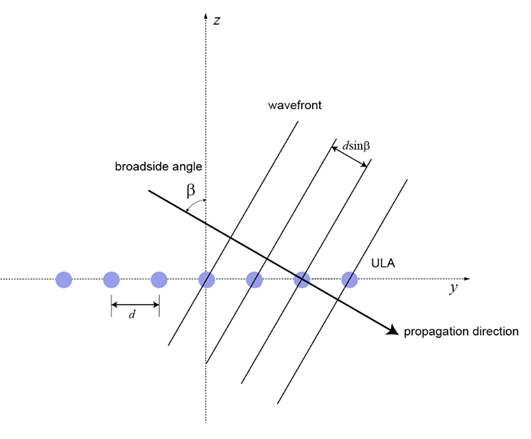

anechoic_target_doa = gcc_estimator([anechoic_mic1_out(:,target_id) anechoic_mic2_out(:,target_id)]) % true value: 0 degree
anechoic_interf_doa = gcc_estimator([anechoic_mic1_out(:,interf_id) anechoic_mic2_out(:,interf_id)]) % true value: 50 degree

**Reverberant Room **

Use the pre-trained speaker separation model to seperate target and interference signals at the two microphone elements respectively:

reverb_mic1_out = separateSpeakersTest(reverb_rcv_noisy(1,:),signal_length,fs);
reverb_mic2_out = separateSpeakersTest(reverb_rcv_noisy(2,:),signal_length,fs);

Calulate the average signal:

reverb_avg_out = (reverb_mic1_out + reverb_mic2_out)/2;
% soundsc(reverb_avg_out(1:num_play_samples,target_id)',fs)
% soundsc(reverb_avg_out(1:num_play_samples,interf_id)',fs)

Estimate the DoA: the broadside-reference arrival angle ([Broadside Angles](https://www.mathworks.com/help/phased/ug/spherical-coordinates.html)) measured from the array normal.

reverb_target_doa = gcc_estimator([reverb_mic1_out(:,target_id) reverb_mic2_out(:,target_id)]) % true value: 0 degree
reverb_interf_doa = gcc_estimator([reverb_mic1_out(:,interf_id) reverb_mic2_out(:,interf_id)]) % true value: 50 degree

#### **Method 2: Combining Signals and then Use separateSpeakers**

Combine the received signals across the 2-microphone elements of the array.

**Use mean value**

anechoic_rcv_mean = mean(anechoic_rcv_noisy,1);
reverb_rcv_mean = mean(anechoic_rcv_noisy,1);

target_anechoic_mean = separateSpeakersTest(anechoic_rcv_mean,signal_length,fs);
% soundsc(target_anechoic_mean(1:num_play_samples,target_id)',fs)
% soundsc(target_anechoic_mean(1:num_play_samples,interf_id)',fs)
target_reverb_mean = separateSpeakersTest(reverb_rcv_mean,signal_length,fs);
% soundsc(target_reverb_mean(1:num_play_samples,target_id)',fs)
% soundsc(target_reverb_mean(1:num_play_samples,interf_id)',fs)

**Use Time Delay Beamforming**

target_anechoic_TDBF = separateSpeakersTest(td_bf_anechoic',signal_length,fs);
target_reverb_TDBF = separateSpeakersTest(td_bf_reverb',signal_length,fs);

## Metics Calculation

This section show how to calculate the required metrics in different cases.

**Anechoic Chamber**

Method1: Use the pre-trained speaker separation model to remove the interference at the two microphone elements respectively:

merics_anechoic_method1 = calcMetrics(target_signal,anechoic_avg_out(:,target_id),fs)

Method 2: Combining Microphone Array Signals and then separateSpeakers

merics_anechoic_method2_mean = calcMetrics(target_signal,target_anechoic_mean(:,target_id),fs)
merics_anechoic_method2_TDBF = calcMetrics(target_signal,target_anechoic_TDBF(:,target_id),fs)

**Reverberant Room **

Method1: Use the pre-trained speaker separation model to remove the interference at the two microphone elements respectively:

merics_reverb_method1 = calcMetrics(target_signal,reverb_avg_out(:,target_id),fs)

Method 2: Combining Microphone Array Signals and then separateSpeakers

merics_reverb_method2_mean = calcMetrics(target_signal,target_reverb_mean(:,target_id),fs)
merics_reverb_method2_TDBF = calcMetrics(target_signal,target_reverb_TDBF(:,target_id),fs)

## Submission Files Generation

Create submission folders.

task1_folder_name = fullfile(pwd, 'Task1_Anechoic');

if ~exist(task1_folder_name, 'dir')
    mkdir(task1_folder_name);
end

task2_folder_name = fullfile(pwd, 'Task2_Reverberant');
if ~exist(task2_folder_name, 'dir')
    mkdir(task2_folder_name);
end

Collect common simulation parameters. 

params.sampling_rate = fs;
params.sound_speed = c;
params.room_dimensions = room_dim;
params.microphone_positions = mic_positions;
params.array_spacing = mic_distance;

params.target_position = target_positions;
params.target_azimuth = target_angles(1);
params.target_hight = target_positions(3);

params.interference_position = interf_positions;
params.interference_azimuth = interf_angles(1);
params.interence_hight = interf_positions(3);

params.sir = desired_sir;
params.snr = desired_snr;

**Anechoic Chamber**

Save signals and paramters for Task 1: Anechoic Chamber (the Time Delay Beamforming case).

interference_signal = interf_signal;
mixture_signal = anechoic_rcv_noisy';
rir_data = rir_anechoic;
processed_signal = target_anechoic_mean(:,target_id);
metrics = merics_anechoic_method2_mean;

save(fullfile(task1_folder_name,['Task1_Anechoic_SNR' num2str(desired_snr) 'db.mat']), ...
    'target_signal','interference_signal','mixture_signal',...
    'processed_signal','rir_data','params','metrics');

audiowrite(fullfile(task1_folder_name,'target_signal.wav'), target_signal, fs);
audiowrite(fullfile(task1_folder_name,'interference_signal1.wav'), interf_signal, fs);

**Reverberant Room**

Save signals and paramters for Task 2: Reverberant Room (the no Beamforming case).

interference_signal = interf_signal;
mixture_signal = reverb_rcv_noisy';
rir_data = rir_reverb;
processed_signal = target_reverb_mean(:,target_id);
metrics = merics_reverb_method2_mean;

save(fullfile(task2_folder_name,['Task2_Reverberant_SNR' num2str(desired_snr) 'db.mat']), ...
    'target_signal','interference_signal','mixture_signal',...
    'processed_signal','rir_data','params','metrics');

audiowrite(fullfile(task2_folder_name,'target_signal.wav'), target_signal, fs);
audiowrite(fullfile(task2_folder_name,'interference_signal1.wav'), interf_signal, fs);

## Helper Functions

**plotRoom**

This helper function is used to plot 3D room with receiver/transmitter points [RIR_SRT].  

function plotRoom(roomDimensions,rx,tx,figHandle)
figure(figHandle)
X = [0;roomDimensions(1);roomDimensions(1);0;0];
Y = [0;0;roomDimensions(2);roomDimensions(2);0];
Z = [0;0;0;0;0];
figure;
hold on;
plot3(X,Y,Z,"k",LineWidth=1.5);
plot3(X,Y,Z+roomDimensions(3),"k",LineWidth=1.5);
set(gca,"View",[-28,35]);
for k=1:length(X)-1
    plot3([X(k);X(k)],[Y(k);Y(k)],[0;roomDimensions(3)],"k",LineWidth=1.5);
end
grid on
xlabel("X (m)")
ylabel("Y (m)")
zlabel("Z (m)")

plot3(tx(1,1),tx(1,2),tx(1,3),"go",LineWidth=2)
plot3(tx(2,1),tx(2,2),tx(2,3),"ro",LineWidth=2)
num_rx = size(rx,1);
for rx_id = 1:num_rx
    plot3(rx(rx_id,1),rx(rx_id,2),rx(rx_id,3),"bx",LineWidth=1)
end
end

**separateSpeakersTest**

This helper function is used to test speaker separation using a pretrained Model [5-6].

function speaker_separated = separateSpeakersTest(rcv_signal,signal_length,fs)
num_speakers = 2;

t_length_frame = 3;                                   % time duration for processing an audio signal
num_samples_per_frame = t_length_frame*fs;            % number of samples in the duration
num_frames = ceil(signal_length/num_samples_per_frame);

extended_signal_length = max(signal_length,num_frames*num_samples_per_frame);
extended_signal = [rcv_signal zeros(1,extended_signal_length-signal_length)];

% audioWriter = audioDeviceWriter('SampleRate',fs, ...
%     'SupportVariableSizeInput', true);
% isAudioSupported = (length(getAudioDevices(audioWriter))>1);
speaker_separated_extend = zeros(extended_signal_length,num_speakers);

for n = 1:num_frames
    idx_start = (n-1)*num_samples_per_frame + 1;
    idx_end = idx_start + num_samples_per_frame - 1;

Call `separateSpeakers.`Number of speakers to separate, specified as `1`, `2`, or `3`. If you do not specify `NumSpeakers`, `separateSpeakers` estimates the number of speakers. You can specify an additional output argument `r` to obtain the residual. For more information, see [One-And-Rest Speech Separation](https://www.mathworks.com/help/audio/ref/separatespeakers.html#mw_7558f471-0e7c-4068-8d37-696e6e6cd3fc_head).

    [y,r] = separateSpeakers(extended_signal(idx_start:idx_end),fs);

    % if isAudioSupported
    %     play(audioWriter,y(:,1));
    % end

    speaker_separated_extend(idx_start:idx_end,1) = y(:,1);
    if size(y,2) > 1
        speaker_separated_extend(idx_start:idx_end,2) = y(:,2);
    end
end
speaker_separated = speaker_separated_extend(1:signal_length,:);
% release(audioWriter)
end

**calcMetrics**

This helper function is used to calculate the required metrics.

function merics = calcMetrics(clean_signal,enhanced_signal,fs)
% merics.osinr = 10*log10(mean(clean_signal.^2)/(mean(enhanced_signal-clean_signal).^2));

Use [`sisnr`](https://www.mathworks.com/help/audio/ref/sisnr.html) to calculate the Scale-invariant signal-to-noise ratio

merics.sisnr = sisnr(enhanced_signal,clean_signal);

Use [`stoi`](https://www.mathworks.com/support/search.html) to calculate the Short-time objective intelligibility measure [9]

merics.stoi = stoi(enhanced_signal,clean_signal,fs);

Use [`visqol`](https://www.mathworks.com/support/search.html) to calculate the Objective metric for perceived audio quality [9]

- `"MOS"` — The output is a scalar representing the mean opinion score (MOS) in the range [1,5], where a higher value corresponds to higher quality.

- `"NSIM"` — The output is a scalar representing the neurogram similarity index measure (NSIM) in the range [-1,1], where 1 corresponds to a perfect similarity between the degraded and reference signals. In practice, the NSIM is generally in the range [0,1].

merics.visqol = visqol(enhanced_signal,clean_signal,fs,Mode="speech",OutputMetric="MOS and NSIM");
end

## References

[1] Acoustic Beamforming Using a Microphone Array: [https://www.mathworks.com/help/audio/ug/acoustic-beamforming-using-a-microphone-array.html](https://ww2.mathworks.cn/help/audio/ug/acoustic-beamforming-using-a-microphone-array.html) 

[2] Beamforming: [https://ww2.mathworks.cn/help/phased/beamforming.html](https://ww2.mathworks.cn/help/phased/beamforming.html) 

[3] Room Impulse Response Simulation with Image Source Method and HRTF Interpolation: [https://www.mathworks.com/help/audio/ug/room-impulse-response-simulation-with-image-source-method-and-hrtf-interpolation.html](https://www.mathworks.com/help/audio/ug/room-impulse-response-simulation-with-image-source-method-and-hrtf-interpolation.html)

[4] Room Impulse Response Simulation with Stochastic Ray Tracing: [https://www.mathworks.com/help/audio/ug/room-impulse-response-simulation-with-stochastic-ray-tracing.html](https://www.mathworks.com/help/audio/ug/room-impulse-response-simulation-with-stochastic-ray-tracing.html)

[5] Direction of Arrival Estimation: [https://ww2.mathworks.cn/help/phased/direction-of-arrival-doa-estimation-1.html](https://ww2.mathworks.cn/help/phased/direction-of-arrival-doa-estimation-1.html)

[6] Compare Speaker Separation Models: [https://www.mathworks.com/help/audio/ug/compare-speaker-separation-models.html](https://www.mathworks.com/help/audio/ug/compare-speaker-separation-models.html) 

[7] Train End-to-End Speaker Separation Model: [https://www.mathworks.com/help/audio/ug/end-to-end-deep-speech-separation.html](https://www.mathworks.com/help/audio/ug/end-to-end-deep-speech-separation.html) 

[8] Denoise Speech Using Deep Learning Networks: [https://ww2.mathworks.cn/help/releases/R2025b/audio/ug/denoise-speech-using-deep-learning-networks.html](https://ww2.mathworks.cn/help/releases/R2025b/audio/ug/denoise-speech-using-deep-learning-networks.html) 

[9] Measuring Speech Intelligibility and Perceived Audio Quality with STOI and ViSQOL: [https://www.mathworks.com/help/audio/ug/measure-speech-intelligibility-and-perceived-audio-quality-with-stoi-and-visqol.html](https://www.mathworks.com/help/audio/ug/measure-speech-intelligibility-and-perceived-audio-quality-with-stoi-and-visqol.html)  

 Copyright 2025 The MathWorks, Inc.